# Deap Learning with MATLAB

## Deep Learning Toolbox

[https://www.mathworks.com/products/statistics.html](https://www.mathworks.com/products/deep-learning.html)

Deep Learning Toolbox™ provides a framework for designing and implementing deep neural networks with algorithms, pretrained models, and apps. 

- use convolutional neural networks (ConvNets, CNNs) and long short-term memory (LSTM) networks to perform classification and regression on image, time-series, and text data

- build network architectures such as generative adversarial networks (GANs) and Siamese networks using automatic differentiation, custom training loops, and shared weights

- design, analyze, and train networks graphically with the Deep Network Designer app

- exchange models with TensorFlow™ and PyTorch through the ONNX format and import models from TensorFlow-Keras and Caffe

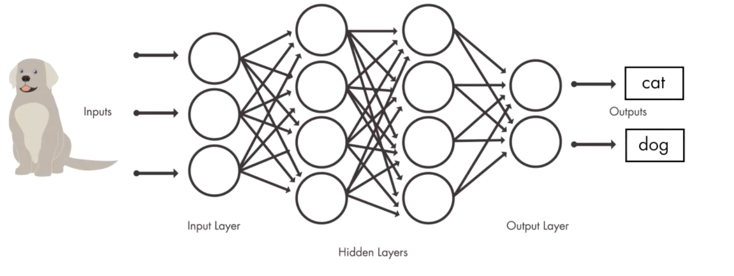

[**Deep Learning Onramp**](https://matlabacademy.mathworks.com/R2020b/portal.html?course=deeplearning) is a nice introduction course.

### Use Pretrained Model

***Deep Learning Toolbox Model for GoogLeNet Network ***

*Install the package use the Add-On Explorer.*

GoogLeNet is a pretrained model that has been trained on a subset of the ImageNet database which is used in the ImageNet Large-Scale Visual Recognition Challenge (ILSVRC). The model is trained on more than a million images, has 144 layers, and can classify images into 1000 object categories (e.g. keyboard, mouse, pencil, and many animals). 

Get the layers from GoogLeNet.

net = googlenet;

Display layers of GoogLeNet

net.Layers

View network architecture

analyzeNetwork(net)

### **Extracting and Visualizing Activations**

Load an image

img = imread("data/cat.jpg");
imshow(img)

Extract features from an input image using a CNN with the `activations` function.

`Y = activations(net, X, layerOut) `returns network activations for a specific layer using the network `net` and the data `X`. Network activations are computed by forward propagating the input X through the network up to the specified layer. 

actvn = activations(net,img,"conv1-7x7_s2");

Normalize the activations using the function `mat2gray` and display multiple images together using the `montage` function 

montage(mat2gray(actvn))

### Demo: Flower Image Classification

#### Get training images

flowerds = imageDatastore("data/Flowers",...
    "IncludeSubfolders",true,"LabelSource","foldernames");

Split into training and testing sets

[trainImgs,testImgs] = splitEachLabel(flowerds,0.7);

Determine the number of flower species

numClasses = numel(categories(flowerds.Labels))

Visualize specific image

img = readimage(flowerds,2);
disp(flowerds.Labels(2))
imshow(img)
img = readimage(flowerds,100);
disp(flowerds.Labels(100))
imshow(img)

### Create a network by modifying GoogLeNet

Modify the classification and output layers

lgraph = layerGraph(net)
lgraph.Layers(end-2:end)

newFc = fullyConnectedLayer(numClasses,"Name","new_fc")
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc)
newOut = classificationLayer("Name","new_out")
lgraph = replaceLayer(lgraph,"output",newOut)
lgraph.Layers(end-2:end)

Plot neural network layer graph

plot(lgraph)

#### Set training algorithm options

Lower the learning rate for transfer learning.

Set the number of epochs and mini-batch size.

- An **iteration** is one step taken in the **gradient descent algorithm** towards minimizing the loss function using a mini-batch. 

- An **epoch** is the full pass of the training algorithm over the entire training set

- Iterations per epoch = Number of training samples / Mini-batch size 

- Number of iterations = Iterations per epoch * Number of epochs

options = trainingOptions("sgdm","InitialLearnRate", 0.01,...
    'MiniBatchSize',100,'MaxEpochs',5,'Plots','training-progress');

#### Perform training

[flowernet,info] = trainNetwork(trainImgs, lgraph, options);

#### Use the trained network to classify test images

testpreds = classify(flowernet,testImgs);

#### Evaluate the results

Calculate the accuracy

nnz(testpreds == testImgs.Labels)/numel(testpreds)

Visualize the confusion matrix

confusionchart(testImgs.Labels,testpreds);

clear; clc

### **Creating Network Architectures from Scratch**

### **Demo: Classify Musical Instruments**

The data set contains spectrograms of 14 musical instruments. It was obtained from from the University of Iowa Electronic Music Studio ([http://theremin.music.uiowa.edu/](http://theremin.music.uiowa.edu/)) and available via MATLAB online course resources. 

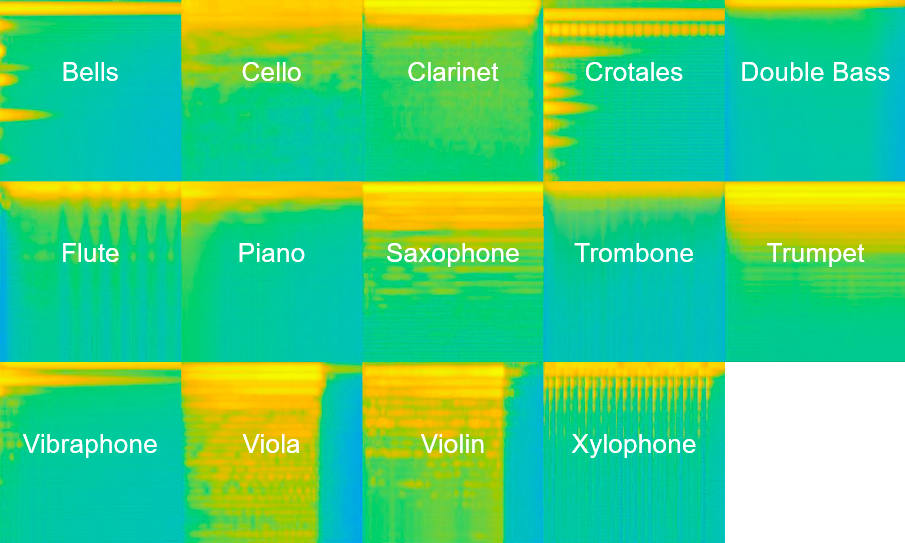

#### Load and split data

The images are stored in the folder `Spectrograms`. The data for each instrument is separated in subfolders, labelled by the folder name.

Split the data so that 80% of the images are used for training, 10% are used for validation, and the rest are used for testing. If changing the image size, make augmented image datastores.

imds = imageDatastore("data/Spectrograms",...
    "IncludeSubfolders",true,"LabelSource","foldernames");
[trainImgs,valImgs,testImgs] = splitEachLabel(imds,0.8,0.1,0.1,"randomized");

trainDs = augmentedImageDatastore([100 100],trainImgs);
valDs = augmentedImageDatastore([100 100],valImgs);
testDs = augmentedImageDatastore([100 100],testImgs);

#### Series architecture from the documentation

You can find the example that uses this architecture in the documentation here: [Speech Recognition](https://www.mathworks.com/help/nnet/examples/deep-learning-speech-recognition.html#d119e1562)

The images are sized `[100 100 3]`.

numClasses = numel(categories(trainImgs.Labels))
dropoutProb = 0.2;
layers = [
    imageInputLayer([100 100 3])

    % A conv layer with 16 filters that have a height and width of 3 
    % Default strid is [1 1],the step size for traversing the input
    % Padding is set so that the output size is ceil(inputSize/stride).
    convolution2dLayer(3,16,"Padding","same")
    batchNormalizationLayer
    reluLayer

    % A max pooling layer with non-overlapping pooling regions,
    % which downsamples by a factor of 2.
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,32,"Padding","same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,"Stride",2,"Padding",[0,1])

    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,"Stride",2,"Padding",[0,1])

    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    dropoutLayer(dropoutProb)
    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer([1 13])

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

layers

#### Train the network

Set the training options and train the network.

options = trainingOptions("adam", ...
    'MaxEpochs',10,...
    "Plots","training-progress", ...
    "ValidationData",valDs, ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropPeriod",15);

scratchNet = trainNetwork(trainDs,layers,options);

#### Evaluate network

Calculate the accuracy on the test dataset.

testPred = classify(scratchNet,testDs);
nnz(testPred == testImgs.Labels)/numel(testImgs.Labels)

Plot confusion matrix

[cmap,clabel] = confusionmat(testImgs.Labels,testPred);
heatmap(clabel,clabel,cmap)

### Practice

Try write your own neural network architecture to classify the instruments.

clear; clc

### LSTM (Long Short-Term Memory) Network

### Demo: Time Series Forecasting for Chickenpox Cases

#### Load, visualize, and process data

Load the months and values of the number of cases of chickenpox (without using datastore).

data = chickenpox_dataset;
data = [data{:}];

figure
plot(data)
xlabel("Month")
ylabel("Cases")
title("Monthly Cases of Chickenpox")

Split into training and test sets at a 80%-20% ratio.

numTimeStepsTrain = floor(0.8*numel(data));

dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);

Standardize data.

mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;

Speicify repsonses (sequence values shifted by one time step).

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

#### Create an LSTM regression network

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 200;

lstmLayers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
lstmLayers

Specify training options.

options = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

Train the network.

lstmNet = trainNetwork(XTrain,YTrain,lstmLayers,options);

#### Make predictions (forcasting)

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
% initialize the network state by predicting on the training data 
lstmNet = predictAndUpdateState(lstmNet,XTrain);
% start from the last time step of the training response
[lstmNet,YPred] = predictAndUpdateState(lstmNet,YTrain(numel(YTrain)));
% loop over the remaining predictions
for i = 2:numel(XTest)
    [lstmNet,YPred(:,i)] = predictAndUpdateState(lstmNet,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

Evaluate performances.

YPred = sig*YPred + mu;
YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)